# FIRST DELIVERABLE SHORT PROJECT

##     BY MARC GUITART & CATERINA MOLL

### A) Containg DICOM information:

#### 1.- Center of the Tumor and estimatesd diameter

- El centro del tumor está en el punto (131, 99, 75) Píxeles = (122.37, 92.47, 105) Milímetros

- El diámetro del tumor está indicado en la figura, el cuál es de 30mm aprox.

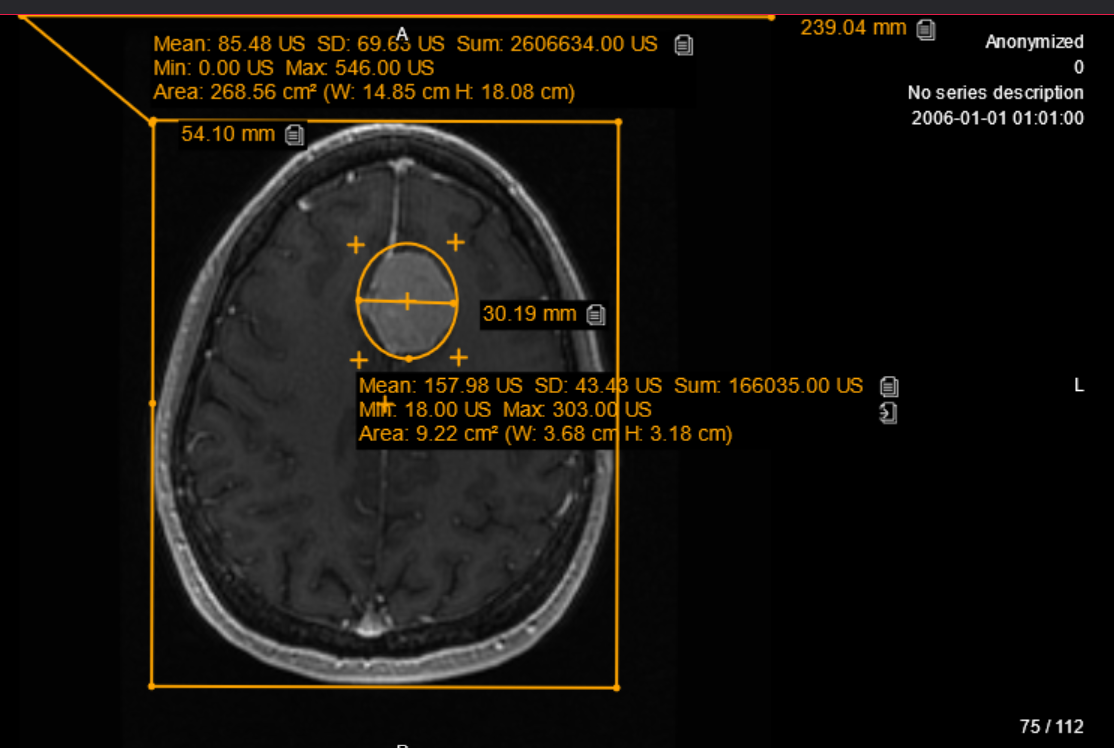

#### 2.- Containing box of the skull and the offset coordinates wrt Image Reference Frame

- El cráneo está emmarcado dentro del recuadro con coordenadas(en píxeles): (44,35,0) (203,35,0) (44,229,0) (203,229,0) (44,35,112) (203,35,112) (44,229,112) (203,229,112)

#### 3.- Fiducial Coordinates

- En píxeles, los fidulares se encuentran en los puntos: (71,212,32) (185,210,65) (122,61,94)

### B) Display in a figure:

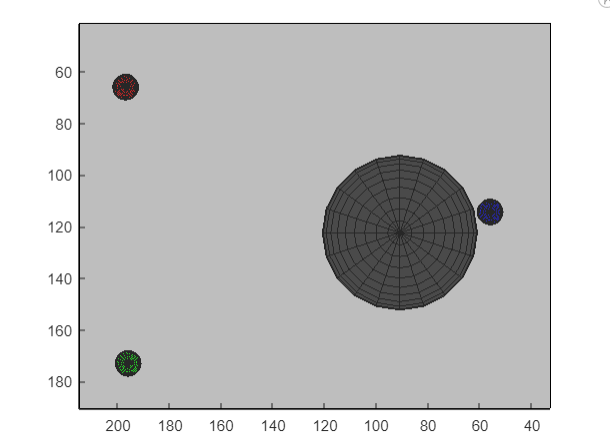

### 1.- The necesary Reference Frames {I} and {CB}

close
clear 
close all
T_1_0=transl(0, 0, 0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_0=transl(41, 32, 0)

T_2_0 =      1     0     0    41
     0     1     0    32
     0     0     1     0
     0     0     0     1


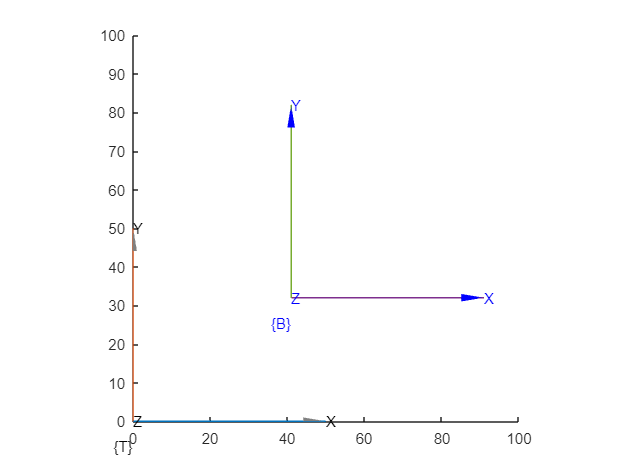

hold on
xlim([0, 100])
ylim([0, 100])
trplot(T_1_0,'framelabel','T' ,'color', 'black','arrow','within', 100, 'length', 50)
trplot(T_2_0,'framelabel','B' ,'color', 'b','arrow', 'within', 100, 'length', 50)

#### 2.- Tha skull containing box

hold on
v= [41.26 214.76 0;190.37 214.76 0;190.37 32.82 0;41.26 32.82 0;41.26 214.76 156.8;190.37 214.76 156.8;190.37 32.82 156.8;41.26 32.82 156.8]

v =    41.2600  214.7600         0
  190.3700  214.7600         0
  190.3700   32.8200         0
   41.2600   32.8200         0
   41.2600  214.7600  156.8000
  190.3700  214.7600  156.8000
  190.3700   32.8200  156.8000
   41.2600   32.8200  156.8000


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5 0.5 0.5],'FaceAlpha',0.3)
view(30,45)
axis equal

#### 3.- The Tumor and fiducials represented by a spheres

r=5 %5 mm

r = 5

hold on
[X,Y,Z] = sphere;
r = 5;
surf(X*r+66,Y*r+197,Z*r+44,'FaceColor',[1 0 0])
axis equal
[X2,Y2,Z2] = sphere;
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 
surf(X2+173,Y2+196,Z2+91,'FaceColor',[0 1 0])
axis equal
[X3,Y3,Z3] = sphere;
X3 = X * r;
Y3 = Y * r;
Z3 = Z * r; 
surf(X3+114.35,Y3+056,Z3+131,'FaceColor',[0 0 1])
axis equal

Ahora representamos la esfera que rodea el tumor, una esfera de diametro 30mm, que equivale a 15mm de radio

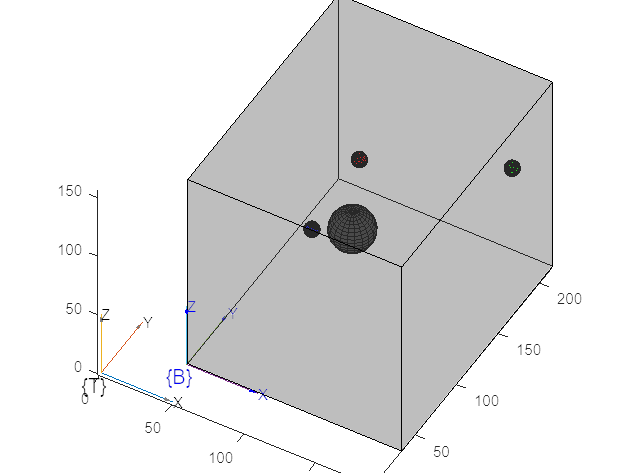

hold on
r = 15;
[X4,Y4,Z4] = sphere;
X4 = X * r;
Y4 = Y * r;
Z4 = Z * r; 
surf(X4+122.37,Y4+90.91,Z4+105,'FaceColor',[0.2 0.2 0.2])
axis equal

Hemos puesto cada fiducial y del tumor con un color distinto para que sean más distingibles y hemos cambiado también el color de la caja contenedora. 